% Load design space data
clear all;
close all;
clc;
data_dir = '../data/';
file = fullfile(data_dir, 'feasible', 'train', 'train_dffnet_max.mat');
feasible_data = load(file);
file = fullfile(data_dir,'base', 'train','train_dffnet_max.mat');
base_data = load(file);

% Combine feasible and base design spaces
xdata = [feasible_data.xdata, base_data.xdata];
ydata = [feasible_data.ydata, base_data.ydata];
% B = sort(ydata);

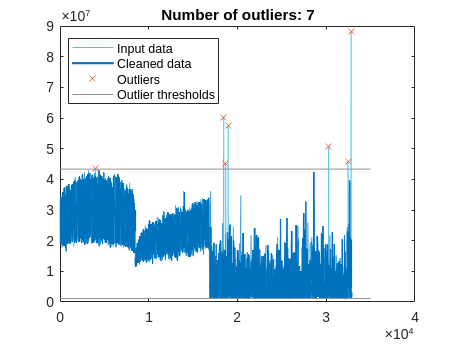

% Remove outliers
[cleanedData,outlierIndices] = rmoutliers(ydata,"percentiles",[0 99.98]);

% Display results
clf
plot(ydata,"Color",[77 190 238]/255,"DisplayName","Input data")
hold on
plot(find(~outlierIndices),cleanedData,"Color",[0 114 189]/255,"LineWidth",1.5,...
    "DisplayName","Cleaned data")

% Plot outliers
plot(find(outlierIndices),ydata(outlierIndices),"x","Color",[217 83 25]/255,...
    "DisplayName","Outliers")
title("Number of outliers: " + nnz(outlierIndices))

% Additional outlier computations for plot
[~,thresholdLow,thresholdHigh] = isoutlier(ydata,"percentiles",[0 99.98]);

% Plot outlier thresholds
plot([xlim missing xlim],[thresholdLow*[1 1] NaN thresholdHigh*[1 1]],...
    "Color",[145 145 145]/255,"DisplayName","Outlier thresholds")

hold off
legend

clear thresholdLow thresholdHigh
% Remove really large outliers (could be from poor simulations)
% [ydata, outlier_idx] = rmoutliers(ydata,"percentiles",[0 99.95]);

% addpath('emitter/');
% extractor_thickness = 76*10^(-6);
% V0 = 1000;
% xbad = xdata(:, outlierIndices);
% for i = 1:length(xbad)
%     d = xbad(1,i);
%     rc = xbad(2,i);
%     alpha = xbad(3,i);
%     h = xbad(4,i);
%     ra = xbad(5,i);
%     emitter = Emitter(d,rc,alpha,h,ra,extractor_thickness,V0);
%     EPOST.solplot(emitter);
% end